# LLENTAB - Prefabricated steel hall

clc;clear all;clearvars;uqlab;close all; addpath 'Functions\'

Copyright 2013-2024, Stefano Marelli and Bruno Sudret.
This is UQLab, version 2.1
UQLab is distributed under the BSD 3-clause open source license available at: 
<a href="https://uqlab.com/license">https://uqlab.com/license</a>.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



## Vazník - Dolní pás

Section properties

section.h_w =  119.0   * 10^-3; % m
section.b   =  110.0   * 10^-3; % m
section.c   =   42.0   * 10^-3; % m
section.e_1 =   55.8   * 10^-3; % m
section.A_g = 1615.93  * 10^-6; % m^2
section.t   =    4.0   * 10^-3; % m
% Material properties

section.f_u =   480.0  * 10^3 ; % kN/m
section.f_y =   420.0  * 10^3  ; % kN/m
% Profile capacity

section.N_cRk =  652.65     ; % kN
section.M_Rk  =   22.57     ; % kNm
% Internal forces - characteristic values
forces.G.N_k = 161.89 * 1.00; %kN
forces.Q.N_k = 140.47 * 1.00; %kN

## Probabilistic reliability analysis

% Probablistic models of variables
% Yeild strength

model.f_y.V_x = 5 / 100; % percent
model.f_y.ratio = 1.09 ;
model.f_y.Dist = 'Lognormal';
model.f_y.nominal = section.f_y;
model.f_y.variable = createUQVariable(model.f_y, 'fy');
InputOpts.Marginals(1) = model.f_y.variable;

% Geometry
model.a.V_x = 3 / 100; % percent
model.a.ratio = 1.00 ;
model.a.Dist = 'Gaussian';
model.a.nominal = section.A_g;
model.a.variable = createUQVariable(model.a, 'A');
InputOpts.Marginals(2) = model.a.variable;

% Pernament load
model.G.V_x = 5 / 100 ;% percent
model.G.ratio = 1.00 ;
model.G.Dist = 'Gaussian';
model.G.nominal = forces.G.N_k;
model.G.variable = createUQVariable(model.G, 'G');
InputOpts.Marginals(3) = model.G.variable;

% Snow load
model.Q.V_x = 50 / 100 ;% percent
model.Q.ratio = 0.40 ;
model.Q.Dist = 'Gumbel';
model.Q.nominal = forces.Q.N_k;
model.Q.variable = createUQVariable(model.Q, 'Q');
InputOpts.Marginals(4) = model.Q.variable;

% Resistance model uncertainty
model.theta_R.V_x = 6 / 100; % percent
model.theta_R.ratio = 1.15 ;
model.theta_R.Dist = 'Lognormal';
model.theta_R.nominal = 1;
model.theta_R.variable = createUQVariable(model.theta_R, 'ThetaR');
InputOpts.Marginals(5) = model.theta_R.variable;

% Load effect model uncertainty
model.theta_E.V_x = 7.5 / 100 ;% percent
model.theta_E.ratio = 1.00 ;
model.theta_E.Dist = 'Lognormal';
model.theta_E.nominal = 1;
model.theta_E.variable = createUQVariable(model.theta_E, 'ThetaE');
InputOpts.Marginals(6) = model.theta_E.variable;

% Vytvoření vstupního objektu pro UQlab
inputOpts.Marginals = InputOpts.Marginals;  % Přiřazení všech marginalit
input = uq_createInput(inputOpts);  % Vytvoření vstupního objektu pro analýzu

## Limit State Function - LSF


$$g(x) = \theta _R \cdot R - \theta _E \cdot (G + Q)$$


N = 10^7; % počet simulací
ModelOpts.mFile = 'limitStateFunction';
ModelOpts.isVectorized = true;

% Vytvoření modelu
myModel = uq_createModel(ModelOpts);
% Nastavení analýzy spolehlivosti metodou FORM
SimOpts.FORM.ComputeSensitivity = true;  % Explicitní příkaz k výpočtu citlivostních indexů
SimOpts.Type = 'Reliability';
SimOpts.Method = 'FORM';  % Změna na FORM metodu
SimOpts.FORM.Search = 'StrongJoint';  % Výběr algoritmu hledání designového bodu
SimOpts.FORM.MaxIterations = 100;  % Maximální počet iterací
SimOpts.FORM.Tolerance = 1e-6;  % Toleranční kritérium konvergence

% Vytvoření a spuštění analýzy
reliability = uq_createAnalysis(SimOpts);


Starting FORM Analysis...

FORM: Finished.


## Reliability Analysis Visualization

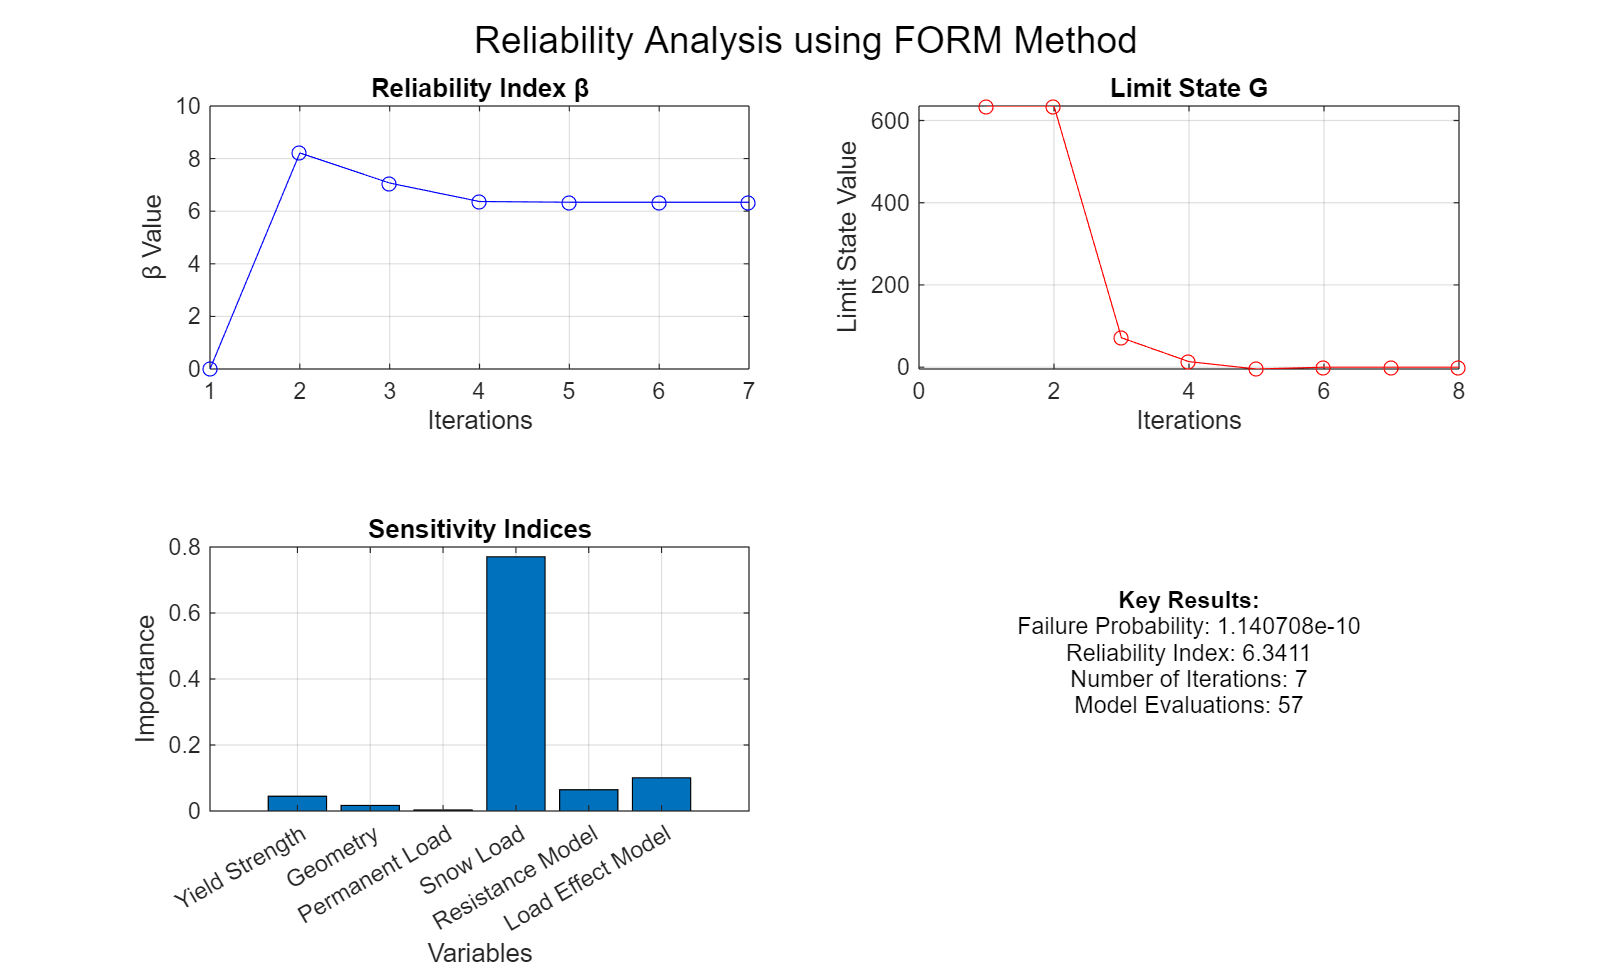

% Extrakce výsledků
results = reliability.Results;

figure('Name', 'Reliability Key Parameters', 'NumberTitle', 'off', 'Position', [100, 100, 1000, 600]);

% 1. Reliability Index (Beta)
subplot(2,2,1);
plot(results.History.BetaHL, 'b-o');
title('Reliability Index β');
xlabel('Iterations');
ylabel('β Value');
grid on;

% 2. Limit State G
subplot(2,2,2);
plot(results.History.G, 'r-o');
title('Limit State G');
xlabel('Iterations');
ylabel('Limit State Value');
grid on;

% 3. Sensitivity Indices
subplot(2,2,3);
bar(results.Importance);
title('Sensitivity Indices');
xlabel('Variables');
ylabel('Importance');
xticklabels({'Yield Strength', 'Geometry', 'Permanent Load', 'Snow Load', 'Resistance Model', 'Load Effect Model'});
grid on;

% 4. Summary of Key Results
subplot(2,2,4);
text(0.5, 0.8, sprintf('Key Results:'), 'FontWeight', 'bold', 'HorizontalAlignment', 'center');
text(0.5, 0.7, sprintf('Failure Probability: %e', results.Pf), 'HorizontalAlignment', 'center');
text(0.5, 0.6, sprintf('Reliability Index: %.4f', results.BetaHL), 'HorizontalAlignment', 'center');
text(0.5, 0.5, sprintf('Number of Iterations: %d', results.Iterations), 'HorizontalAlignment', 'center');
text(0.5, 0.4, sprintf('Model Evaluations: %d', results.ModelEvaluations), 'HorizontalAlignment', 'center');
axis off;

% Overall title
sgtitle('Reliability Analysis using FORM Method', 'FontSize', 16);

% Appearance adjustment
set(gcf, 'Color', 'white');


% Save graph
if ~exist('Plots', 'dir')
   mkdir('Plots')
end
% Print key numerical results
fprintf('\nKey Reliability Analysis Results:\n');


Key Reliability Analysis Results:


fprintf('Failure Probability: %e\n', results.Pf);

Failure Probability: 1.140708e-10


fprintf('Reliability Index: %.4f\n', results.BetaHL);

Reliability Index: 6.3411


fprintf('Number of Iterations: %d\n', results.Iterations);

Number of Iterations: 7


fprintf('Number of Model Evaluations: %d\n', results.ModelEvaluations);

Number of Model Evaluations: 57



% Interpretation of results
fprintf('\nResults Interpretation:\n');


Results Interpretation:


fprintf('- Extremely low failure probability (%.2e)\n', results.Pf);

- Extremely low failure probability (1.14e-10)


fprintf('- High reliability index (%.4f)\n', results.BetaHL);

- High reliability index (6.3411)


fprintf('- Convergence achieved in %d iterations\n', results.Iterations);

- Convergence achieved in 7 iterations
